# Polinomios

En matlab se puede definir a los polinomios mediante un vector fila, ejemplo:

                                       
$$x^3+2x$$


Como:

polinomio=[1 0 2 0];

Se pueden encontrar sus raíces de la siguiente forma

raices=roots(polinomio)

Podemos volver a obtener el polinomio a partir de sus raices:

p=poly(raices)

Para evaluar el polinomio en un punto dado x tenemos que usar la funcion polyval(), ejemplo:

p=[1 -1 -1 1]
polyval(p,2)

Para multiplicar y dividir polinomios estan las funciones conv() y deconv() (estas funciones tambien sirven para el tratamiento da imagenes, conv es de la operacion convolucional). Ejemplo:

p1=[1, -2, 1]; p2=[1,1]; p3=conv(p1,p2)
p4=deconv(p3,p2)
[p4,r]=deconv(p3,p2) % resto de la división

Ejercicio sencillo:

Considera el siguiente polinomio

$p(x)=x-1
$, calcular $p(x)^3
$

p=[1 -1];
conv(p,conv(p,p))

# Interpolación y ajuste de datos

## Interpolación polinómica

Sean $(x_i,y_i),i=1,2,...,n$ pares de n puntos , podemos calcular los coeficientes del polinomio de grado n-1 que pasa por los n puntos de la siguiente forma:

                        
$$c=polyfit(x,y,n-1)$$


Donde 'x' y 'y' son vectores de longitud n y c (que almacena lo que regresa la funcion polyfit) contiene a los coeficientes del polinomio de interpolacion:


$$p(x)=c_1x^{n-1}+c_2x^{n-2} + ...+c_{n-1}x+c_n$$


Ejemplo: Calcular el polinomio de grado 2 que pasa por los puntos: (1,-3),(2,1),(3,3), representar su grafica en el intervalo [0,10] señalando los puntos interpolados

x=[1 2 3];
y=[-3 1 3];
c=polyfit(x,y,length(x)-1)    
%Graficando
z=linspace(0,10);
p=polyval(c,z);
figure('Name','Uno')
hold on
plot(z,p);
plot([-1,10],[0,0],'ko','LineWidth',0.8);
plot([0,0],[-10,8],'k','LineWidth',0.8);
plot(x,y,'ro');
axis([-2,10,-11,10]);
hold off


length(L)-1

Ejercicios:

1.Uno de los factores que afectan la temperatura del aire depende de la concentracion K de acido carbonico en el aire, se tienen los siguientes datos para diferentes latitudes sobre la Tierra y para el valor de K= 0.67 se presenta la variacion $\delta k
$. 

- Calcular $\delta k
$ para una L =10.

- Dibujar el polinomio de interpolacion

- Insertar los marcadores de puntos

L=[-55 -25 5 35 65];
dK=[-3.25 -3.2 -3.02 -3.32 -3.1];
c=polyfit(L,dK,length(L)-1);
z=linspace(-60,70);
length(z)
p=polyval(c,z)
figure('Name','Dos')
hold on
title('Interpolacion polinomica')
plot(z,p,'b','LineWidth',1.2);
plot(L,dK,'ro','MarkerSize',...
    15);
xlabel('X');
ylabel('Y');
hold off
delta=polyval(c,10)

2. Calcular el polinomio de grado 10 para los siguientes datos:

x=[0 2 3 5 6 8 9 11 12 14 15];
y=[10 20 30 -10 10 10 10.5 15 50 60 85];
c=polyfit(x,y,length(x)-1)
z=linspace(0,15);
p=polyval(c,z);
figure('Name','Tres')
hold on
plot(x,y,'ro')
plot(z,p)
hold off


- Dibujar el polinomio

- Insertar los marcadores

3. Calcular el polinomio de grado 5 que interpola los siguientes valores:

x=[0.01 2.35 1.67 3.04 2.35 1.53];

y=[6 5 4 3 2 3];

## Interpolación lineal por secciones

Cuando se tienen un gran numero de datos, la interpolacion polinomica es inprecisa, para ello la interpolacion lineal por secciones es de gran ayuda, la funcion en MATLAB es la siguiente:

v1=interp1(x,y,z)

Donde:

x, y son dos vectores del mismo tamaño 

z son las abscisas del punto a interpolar, puede ser una matriz.

v1 son los valores calculados

Tomando los valores de ejercicio dos:

- Calcular la interpolacion polinomica cuando x=1

- Calcular la interpolacion por secciones cuando x=1

- Comparar ambos valores

- Graficar ambas interpolaciones

x=[0 2 3 5 6 8 9 11 12 14 15];
y=[10 20 30 -10 10 10 10.5 15 50 60 85];
v1=interp1(x,y,1)
c=polyfit(x,y,10);
s=polyval(c,1)
%Graficando
equis=linspace(0,16);
p=polyval(c,equis);
plot(x,y,x,y,'o',equis,p);
axis([-1,16,-400,150]);

## Interpolación con spline

A diferencia de la interpolacion lineal por secciones la interpolacion con splines crea una funcion suave, la funcion en matlab es: 

        s = spline(x,y,z)

Con los datos del ejercicio anterior calcular una nueva interpolacion con la funcion spline y graficar ambas interpolaciones en una misma grafica.

x=[0 2 3 5 6 8 9 11 12 14 15];
y=[10 20 30 -10 10 10 10.5 15 50 60 85];
z=linspace(0,15);
s=spline(x,y,z);
figure('Name','Splines')
plot(x,y,'ro',z,s,x,y,'g','LineWidth',2);
%axis([-1,5,-20,20]);

## Ajuste de datos por polinomios

En el caso de las interpolaciones, la funcion creada pasa justo por encima de los datos, muchas veces nosotros no queremos que esto suceda sino que se ajuste una linea lo mejor posible, para ello esta el ajuste por minimos cudrados.

**Ya lo vimos!!!!!!!**

Directo al ejercicio:

Calcular las curvas de ajuste de grado 1, 2, 3 y 6 para los siguientes datos y graficar de una forma nueva:

x=[0.9 1.5 3 4 6 8 9.5];
y=[0.9 1.5 2.5 5.1 4.5 4.9 6.3];
%por una recta
p1=polyfit(x,y,1);
figure('Name','Minimos cuadrados')
subplot(2,2,1);
plot(x,y,'o',[0,10],[polyval(p1,0),polyval(p1,10)]);
title('Ajuste por una recta');

x=[0.9 1.5 3 4 6 8 9.5];
y=[0.9 1.5 2.5 5.1 4.5 4.9 6.3];
%por una recta
p1=polyfit(x,y,1);
figure('Name','Minimos cuadrados')
subplot(2,2,1);
plot(x,y,'o',[0,10],[polyval(p1,0),polyval(p1,10)]);
title('Ajuste por una recta');
%por una parabola
p2=polyfit(x,y,2);
xp=linspace(0,10);
subplot(2,2,2);
plot(x,y,'o',xp,polyval(p2,xp));
title('Ajuste por una parabola');

p3=polyfit(x,y,3);
subplot(2,2,3);
plot(x,y,'o',xp,polyval(p3,xp));
title('Ajuste grado 3')
axis([1,6,-10,10])


p4=polyfit(x,y,6);
subplot(2,2,4);
plot(x,y,'o',xp,polyval(p4,xp));
title('Ajuste grado 6')


# Resolucion de ecuaiones no lineales

## Resolución de ecuaciones polinómicas

**Ya lo vimos!!!!**

Directo a un ejercicio:

Determinar el volumen V que ocupa un gas a partir de la siguiente ecuacion de estado:

                                                    
$$[p+ a(\frac{N}{V})^2](V-Nb)=kNT$$


donde:

- N es el numero de moleculas

- k es la cte de boltzman

- a y b son ctes que dependen del gas

Al realizar un poco de algebra la expresion anterior cambia a :

                                
$$f(V)=pV^3-(pbN+kNT)V^2+aN^2V-abN^3=0$$


Datos para el dioxido de carbono:

- k=1.3806503E-23 J/K

- a=0.401 $Pa \quad m^6
$

- b= 42.7 E-6 $m^3
$

- N=1000 moleculas

- T=300 K

- p = 3.5E7 Pa

T = 300 %K
p = 3.5e7% Pa
N = 1000
k = 1.3806503e-23% Joule/K
a = 0.401 %Pa m6
b = 42.7e-6 %m3
% Coeficientes del polinomio f(V)=c1*V^3 + c2*V^2 + c3*V + c4
c1 = p;
c2 = -(p*b+k*T)*N;
c3 = a*N*N;
c4 = -a*b*N*N*N;
c = [c1,c2,c3,c4]

% raices del polinomio
sol = roots(c)

% seleccion de las raices reales
V = [];
for j = 1:3
if(isreal(sol(j)))
V = [V,sol(j)]
end
end
% grafica de la función f(V)
z = linspace(-0.1,0.1);
vz = polyval(c,z);
plot(z,vz,'LineWidth',1.2)
hold on
% solucion
plot(V,polyval(c,V),'ro','LineWidth',1.2)
plot([-0.1,0.1],[0,0],'k')
plot([0,0],[-1.e5,1.e5],'k')
xlabel('Volumen');
ylabel('f(V)');
% parte visible
axis([-0.1,0.1,-1.e5,1.e5])
hold off

## Resoluición de funciones no lineales

Las ecuaciones de una variable que podamos escribir de la forma *f(x)=0* se resolverán con la función **fzero**, cuya sintáxis es la siguiente:

- x = fzero(fun,x0)        regresa el valor de x donde la función es igual a cero

- x = fzero(fun,x0,options)        options modifica la salida, podemos ver las iteraciones realizadas   

- x = fzero(problem)        encuentra las raíces de un problema especificado por *problem*

- [x, fval,exitflag,output] = fzero(...) nos regresa la funcion valuada en la solucion, porque se detuvo fzero e información detallada del proceso. 

Ejemplo:

Sea la funcion $f(x) = x +ln(\frac{x}{3})=0$, encontrar las raices de la funcion

f=@(x) x+log(x/3)
fplot(f,[-5,10]);
options=optimset('Display','iter');
[x, fval,exitflag,output]=fzero(f,1,options)
eps
%x=fzero(f,[0.5,2],options)

Ejercicio, calcular las soluciones de la funcion $sin(\frac{x}{2}) cos(\sqrt{x})=\frac{1}{5} $ en el intervalo [0,pi]

fun=@(x) sin(x/2).*cos(sqrt(x))- 0.2;
fun(2)
data = linspace(0,pi);
plot(data,fun(data));
grid on
fzero(fun,0.5)
fzero(fun,1.5)

## Resoluciones de sistemas de ecuaciones no lineales

Si el sistema de ecuaciones es no lineal, el operador \ entre matrices no sirve para resolver el sistema, para ello esta la función **fsolve **y la sintáxis es la siguiente:

- x = fsolve(fun,x0)        nos regresa un arreglo con las soluciones

- x = fsolve(fun,x0,options)

- x = fsolve(problem)

- [x,fval] = fsolve(_)

- [x,fval,exitflag,output,jacobian] = fsolve(**_**

Ejemplo:

Se presenta el siguiente sistema de ecuaciones: 


$$\mathrm{e}^{- \mathrm{e}^{\mathrm{x2} - \mathrm{x1}}} - \mathrm{x2}\, \left({\mathrm{x1}}^2 + 1\right) = 0$$



$$\mathrm{x1}\, \cos\!\left(\mathrm{x2}\right) + \mathrm{x2}\, \sin\!\left(\mathrm{x1}\right) - \frac{1}{2} = 0$$


fun=@sistemaNoLineal
x0=[0,0]
[x,fval,exitflag,output,jacobian]=fsolve(fun,x0)


# Integración numérica

Para integrar tenemos 3 funciones principales, las cuales son: **integral, integral2, integral3**, se muestra la sintaxis de cada una de ellas:)

- q = integral(fun,xmin,xmax)

- q = integral2(fun,xmin,xmax,ymin,ymax)

- q = integral3(fun,xmin,xmax,ymin,ymax,zmin,zmax)

Cada una nos regresa el resultado de integrar la función en el intervalo especificado. 

Ejemplo:

                                                    
$$f(x)=\frac{1}{4x^2+e^{3c}$$


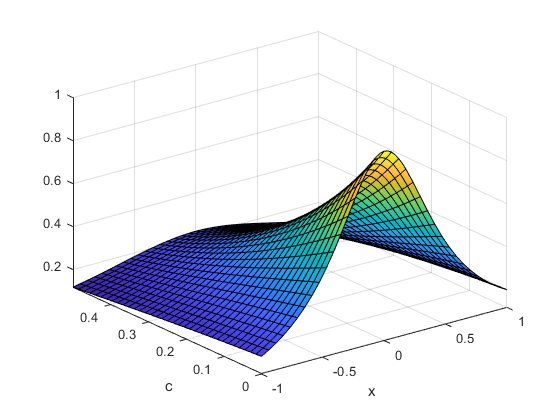

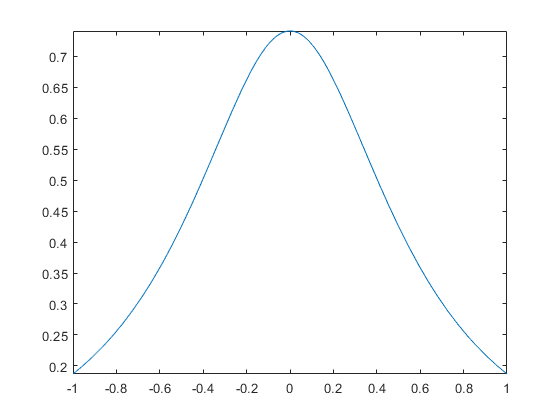

ans = 0.8990

ans = 0.1000

fun=@(x,c) 1./(4*x.^2+exp(3*c));
fsurf(fun,[-1,1,0,0.5]);
xlabel('x')
ylabel('c')
fplot(@(x)fun(x,0.1),[-1,1])
%quad(@(x)fun(x,0.1),-1,1)
integral(@(x)fun(x,0.1),-1,1)
integral2(fun,-1,1,0,0.1)